# Adding a Spatial Reference to Eye Scans

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

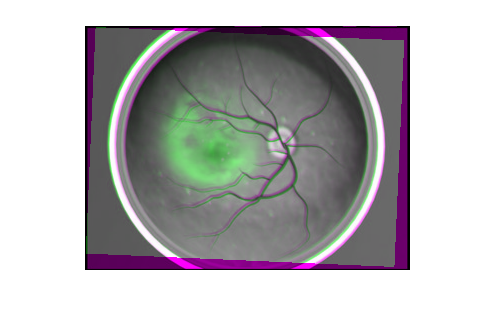

early = imread("./images/earlyAMD.jpg");
advanced = imread("./images/advancedAMD.jpg");

tFormAMD = imregcorr(advanced, early);
advTransform = imwarp(advanced, tFormAMD);
imshowpair(advTransform, early)


movTransfSz = size(advTransform)

movTransfSz =    242   320     3


fixSz = size(early)

fixSz =    244   325     3


## Task 1

You can create a spatial reference for an image by passing the size of the image to `imref2d`.

`spRef` `=` `imref2d``(``szFixed``)`

The output `spRef` is a spatial referencing object whose properties define a two-dimensional spatial frame of reference based on the image size.

Rfixed = imref2d(fixSz)

Rfixed =   imref2d with properties:

           XWorldLimits: [0.5000 325.5000]
           YWorldLimits: [0.5000 244.5000]
              ImageSize: [244 325]
    PixelExtentInWorldX: 1
    PixelExtentInWorldY: 1
    ImageExtentInWorldX: 325
    ImageExtentInWorldY: 244
       XIntrinsicLimits: [0.5000 325.5000]
       YIntrinsicLimits: [0.5000 244.5000]


## Task 2

To use a spatial referencing object with `imwarp`, use the `"OutputView"` name-value pair with the spatial reference as the value.

`imgT` `=` `imwarp``(``img``,``tForm``,``"OutputView"``,``spRef``)``;`

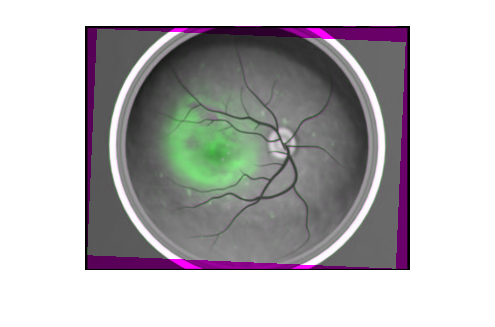

advTransform = imwarp(advanced, tFormAMD, "OutputView", Rfixed);
imshowpair(advTransform, early)